# `锂电池故障诊断实验`

`工作内容：`

`1. 数据集预处理`

`2.`` 特征工程`

`3.`` 数据集划分`

`4.`` 模型学习`

- `BP神经网络`

- `测试集验证`

- `分类结果`

`5.`` 测试集打分及模型评估`

`6.`` 模型参数优化`

- `特征变量分别训练`

- `主成分分析`

- `网格搜索交叉验证`

`7. 验证集打分及模型评估`

## `1. 数据集预处理`

`本节首先导入数据集battery_fault_diagnosis.mat，首先要查看样本集的特征变量数和分类标签数，观查其统计信息。`

clc
clear
close all

load battery_fault_diagnosis.mat

发现其后四列数据没有变化，所以在后续分类过程中剔除这四列。统计output里面的故障组合程度。

b=output(:,1)*1+output(:,2)*2+output(:,3)*4

b =      1
     0
     3
     3
     7
     5
     4
     3
     1
     2


a=zeros(1,8);
for i=2:8
    for j=1:10000
        if b(j)==(i-1)
            a(i)=a(i)+1;
        end
    end
end
a(1)=10000-a(2)-a(3)-a(4)-a(5)-a(6)-a(7)-a(8)

a =         1234        1211        1275        1275        1216        1259        1237        1293


这里观察后发现，各种故障组合都差不多，真好。

下面对各变量做特征工程。

## 2. 数据集处理与特征工程

真好，首先先做一个特征变量标准化。

X=input(:,1:9);
Max=zeros(1,9);
Min=zeros(1,9);
for i=1:9
    [u,v]=max(X(:,i));
    Max(i)=u;
    [w,z]=min(X(:,i));
    Min(i)=w;
end

Xs=zeros(10000,9);
for i=1:9
    Xs(:,i)=(X(:,i)-Min(i))./(Max(i)-Min(i));
end

标准化做完了，接下来看一下这九个特征变量到三个分类标签的相关系数。

y=output

y =      1     0     0
     0     0     0
     1     1     0
     1     1     0
     1     1     1
     1     0     1
     0     0     1
     1     1     0
     1     0     0
     0     1     0


Ex=zeros(1,9);
Ey=zeros(1,3);
Ex2=zeros(1,9);
Ey2=zeros(1,3);
Exy=zeros(9,3);

for i=1:9
    Ex(i)=sum(Xs(:,i))/10000;
    Ex2(i)=sum(Xs(:,i).^2)/10000;
end
for i=1:3
    Ey(i)=sum(y(:,i))/10000;
    Ey2(i)=sum(y(:,i).^2)/10000;
end
for i=1:9
    for j=1:3
        Exy(i,j)=( sum(Xs(:,i).*y(:,j)) )/10000;
    end
end

rho=zeros(9,3);
for i=1:9
    for j=1:3
        rho(i,j)=(Exy(i,j)-Ex(i)*Ey(j))/(sqrt(Ex2(i)-Ex(i)^2) * sqrt(Ey2(j)-Ey(j)^2));
    end
end

很有意思，这个数据的相关矩阵很标准。是不是软件仿真出来的呀。

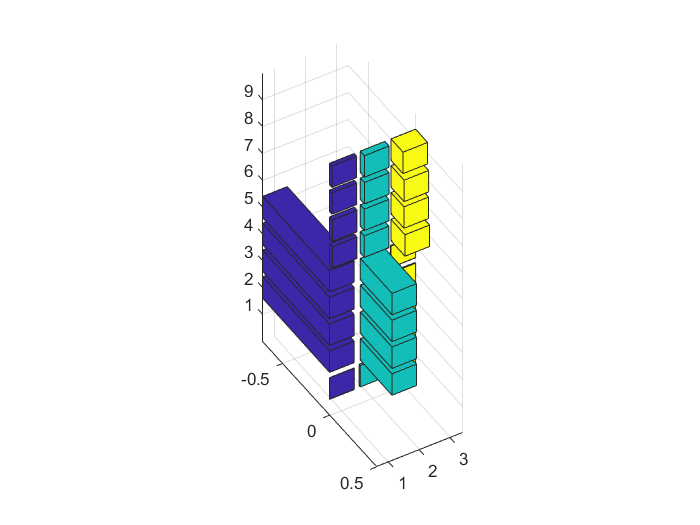

## 3. 划分一下数据集吧

其实老师做了一个固定的划分方法，那就这样吧。

后面交叉验证啥的再说。

train_x=Xs(1:6000,:)';
train_y=y(1:6000,:)';
test_x=Xs(8001:10000,:)';
test_y=y(8001:10000,:)';
vali_x=Xs(6001:8000,:)';
vali_y=y(6001:8000,:)';

## 4. 模型学习

### 4.1 BP神经网络

先做一个简简单单的神经网络捏

%节点个数
inputnum = 9; % 输入层节点数量
hiddennum = [20,20]; % 隐含层节点数量
outputnum = 3; % 输出层节点数量

%% 第四步 构建BP神经网络
net = newff(train_x, train_y, [20,20], {'tansig', 'purelin'}, 'trainlm'); % 建立模型，传递函数使用purelin，采用梯度下降法训练

W1 = net. iw{1, 1}; %输入层到中间层的权值
B1 = net.b{1}; %中间各层神经元阈值

W2 = net.lw{2, 1}; %中间层到输出层的权值
B2 = net. b{2}; %输出层各神经元阈值

%% 第五步 网络参数配置（ 训练次数，学习速率，训练目标最小误差等）
net.trainParam.epochs = 10000; % 训练次数，这里设置为1000次
net.trainParam.lr = 0.01; % 学习速率，这里设置为0.01
net.trainParam.goal = 0.0001; % 训练目标最小误差，这里设置为0.00001

%% 第六步 BP神经网络训练
net = train(net, train_x, train_y); %开始训练，其中inputn,outputn分别为输入输出样本

%% 第八步 BP神经网络预测
vali_simu = sim(net, vali_x); %用训练好的模型进行仿真

这里做完了，然后认为大于0.5的置信度为1，小于0.5的置信度为0。

vali_y1=zeros(3,2000);
for i=1:2000
    for j=1:3
        if vali_simu(j,i)<0.5
            vali_y1(j,i)=0;
        else 
            vali_y1(j,i)=1;
        end
    end
end

简单打个分吧

p=0.5;
cmx1=cmatrix(vali_simu(1,:),vali_y(1,:),p);
cmx2=cmatrix(vali_simu(2,:),vali_y(2,:),p);
cmx3=cmatrix(vali_simu(3,:),vali_y(3,:),p);

还要看一下整体的

b=vali_y1(1,:)*1+vali_y1(2,:)*2+vali_y1(3,:)*4;
c=vali_y(1,:)*1+vali_y(2,:)*2+vali_y(3,:)*4;
cmx_all=zeros(2,1);
for i=1:2000
    if b(i)==c(i)
        cmx_all(1)=cmx_all(1)+1;
    else 
        cmx_all(2)=cmx_all(2)+1;
    end
end

存一下8

save('netbp1.mat','net');       % 将网络net保存为.mat文件，后面可直接调用

### 4.2 SVM

暂时不想做

### 4.3 分类树

暂时不想做

### 4.4 逻辑回归

暂时不想做

### 4.5 KNN

暂时不想做

## 5. 测试集打分及模型评估

close all
[Acc1,Per1,rec1,f1_1]=modelscore(cmx1)

Acc1 = 0.9345

Per1 = 0.9436

rec1 = 0.9280

f1_1 = 0.9358


[Acc2,Per2,rec2,f1_2]=modelscore(cmx2)

Acc2 = 0.9295

Per2 = 0.9343

rec2 = 0.9220

f1_2 = 0.9281


[Acc3,Per3,rec3,f1_3]=modelscore(cmx3)

Acc3 = 0.9495

Per3 = 0.9464

rec3 = 0.9494

f1_3 = 0.9479


Acc_all=cmx_all(1)/length(vali_y)

Acc_all = 0.8235

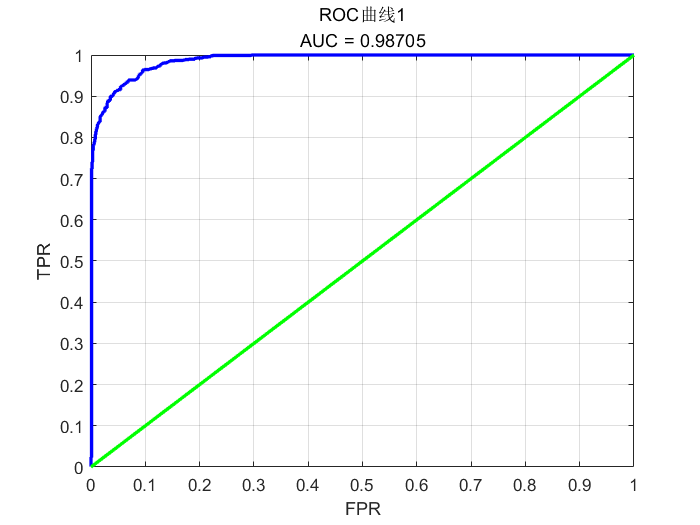


[FPR_p1,TPR_p1,AUC1] = AUCROC(vali_simu(1,:),vali_y(1,:));
[FPR_p2,TPR_p2,AUC2] = AUCROC(vali_simu(2,:),vali_y(2,:));
[FPR_p3,TPR_p3,AUC3] = AUCROC(vali_simu(3,:),vali_y(3,:));

%画ROC图1
figure(1)
plot(FPR_p1,TPR_p1,'b',"LineWidth",2);
title({'ROC曲线1', ['AUC = ', num2str(AUC1)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_p1,FPR_p1,'g',"LineWidth",2);

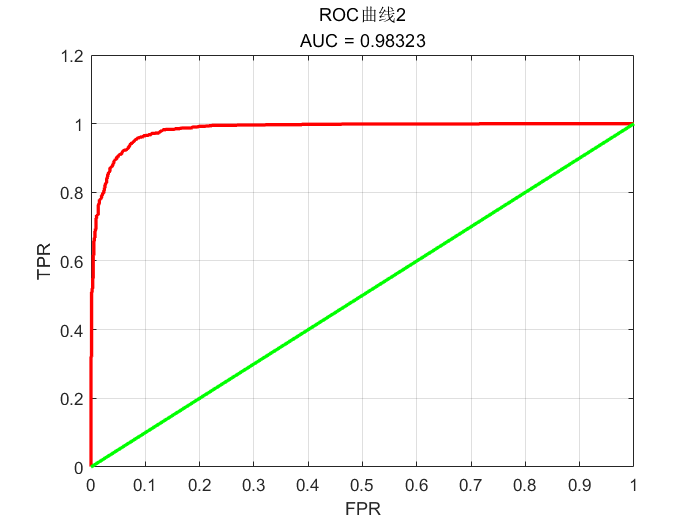


%画ROC图2
figure(2)
plot(FPR_p2,TPR_p2,'r',"LineWidth",2);
title({'ROC曲线2', ['AUC = ', num2str(AUC2)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_p2,FPR_p2,'g',"LineWidth",2);

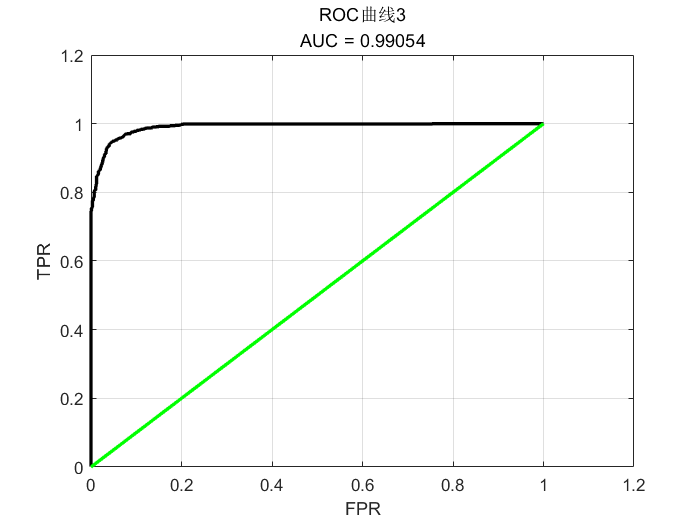


%画ROC图3
figure(3)
plot(FPR_p3,TPR_p3,'k',"LineWidth",2);
title({'ROC曲线3', ['AUC = ', num2str(AUC3)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_p3,FPR_p3,'g',"LineWidth",2);

我觉得效果还行，甚至都不用单独再做了。真好。

## 6. 模型参数优化

我们先做一个工作，前面已经说了，单一分类标签的与单一特征变量的相关性有很明显的区别。

- 特征变量X2, X3, X4, X5对分类Y1有明显的负相关性；

- 特征变量X2, X3, X4, X5对分类Y2有明显的正相关性；

- 特征变量X6, X7, X8, X9对分类Y3有一定的正相关性；

我们这里做两个工作

- 9条特征变量作为输入，单一分类标签作为输出，对每一条分类单独做分类建模；

- 只选取强相关性的特征变量做输入，单一分类标签作为输出，对每一条分类单独做建模。

### 6.1 第一个工作

#### 6.1.1 第一条分类

close
[net1,vali_simu1] = naiveBPN(train_x,train_y(1,:),vali_x,hiddennum);

p=0.5;
cmx_1=cmatrix(vali_simu1,vali_y(1,:),p);
[Acc_1,Per_1,rec_1,f1_1]=modelscore(cmx_1)

Acc_1 = 0.9515

Per_1 = 0.9575

rec_1 = 0.9472

f1_1 = 0.9523

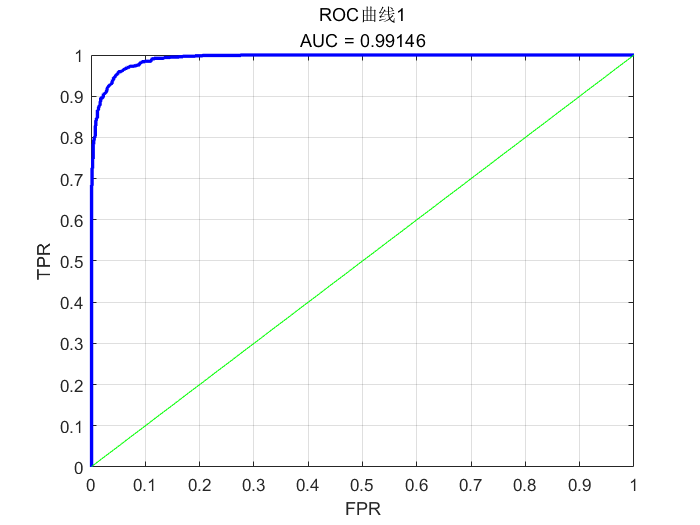

[FPR_1,TPR_1,AUC_1] = AUCROC(vali_simu1,vali_y(1,:));

%画ROC图4
figure(4)
plot(FPR_1,TPR_1,'b',"LineWidth",2);
title({'ROC曲线1', ['AUC = ', num2str(AUC_1)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_1,FPR_1,'g');


save('netbp_1.mat','net1');  

#### 6.1.2 第二条分类

close
[net2,vali_simu2] = naiveBPN(train_x,train_y(2,:),vali_x,hiddennum);

p=0.5;
cmx_2=cmatrix(vali_simu2,vali_y(2,:),p);
[Acc_2,Per_2,rec_2,f1_2]=modelscore(cmx_2)

Acc_2 = 0.9345

Per_2 = 0.9405

rec_2 = 0.9262

f1_2 = 0.9333

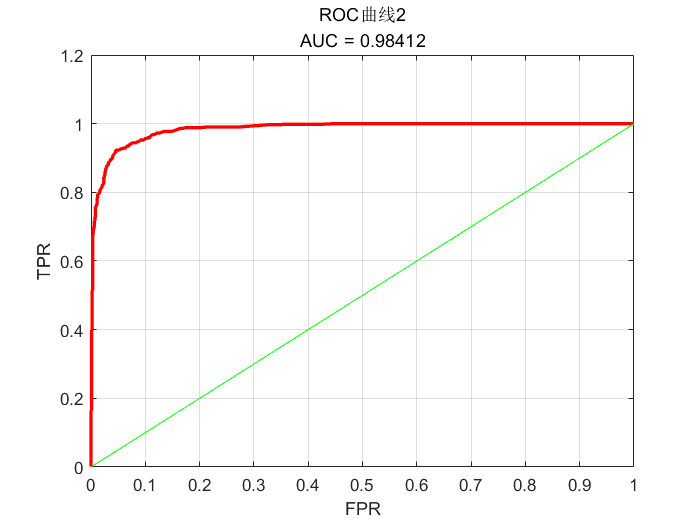

[FPR_2,TPR_2,AUC_2] = AUCROC(vali_simu2,vali_y(2,:));

%画ROC图4
figure(5)
plot(FPR_2,TPR_2,'r',"LineWidth",2);
title({'ROC曲线2', ['AUC = ', num2str(AUC_2)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_2,FPR_2,'g');


save('netbp_2.mat','net2');

#### 6.1.3 第三条分类

close
[net3,vali_simu3] = naiveBPN(train_x,train_y(3,:),vali_x,hiddennum);

p=0.5;
cmx_3=cmatrix(vali_simu3,vali_y(3,:),p);
[Acc_3,Per_3,rec_3,f1_3]=modelscore(cmx_3)

Acc_3 = 0.9670

Per_3 = 0.9701

rec_3 = 0.9622

f1_3 = 0.9662

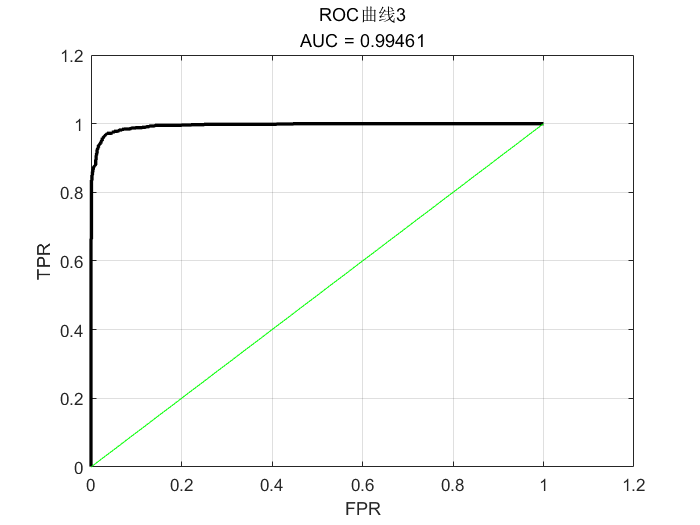

[FPR_3,TPR_3,AUC_3] = AUCROC(vali_simu3,vali_y(3,:));

%画ROC图4
figure(6)
plot(FPR_3,TPR_3,'k',"LineWidth",2);
title({'ROC曲线3', ['AUC = ', num2str(AUC_3)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_3,FPR_3,'g');


save('netbp_3.mat','net3');

这三者和原来那个的F1-score基本上没什么差别（认为F1-score波动3%以内都算没明显变换），结了，做下一个项目。

### 6.2 第二个工作

#### 6.2.1 第一条分类

% close 
% [net1,vali_simu1] = naiveBPN(train_x(2:5,:),train_y(1,:),vali_x(2:5,:),[20,20]);
% 
% p=0.5;
% cmx_1=cmatrix(vali_simu1,vali_y(1,:),p);
% [Acc_1,Per_1,rec_1,f1_1]=modelscore(cmx_1)
% [FPR_1,TPR_1,AUC_1] = AUCROC(vali_simu1,vali_y(1,:));
% 
% %画ROC图4
% figure(7)

Acc_1 = 0.8510

Per_1 = 0.8536

rec_1 = 0.8519

f1_1 = 0.8528

% plot(FPR_1,TPR_1,'b');
% title({'ROC曲线1', ['AUC = ', num2str(AUC_1)]});
% xlabel("FPR");
% ylabel("TPR");
% hold on
% grid on
% plot(FPR_1,FPR_1,'g');
% 
% save('netbp_1minus.mat','net1');  

好家伙我觉得不得行了已经，这个结果明显差一截，差超过5%就算明显，就很差。

#### 6.2.2 第二条分类

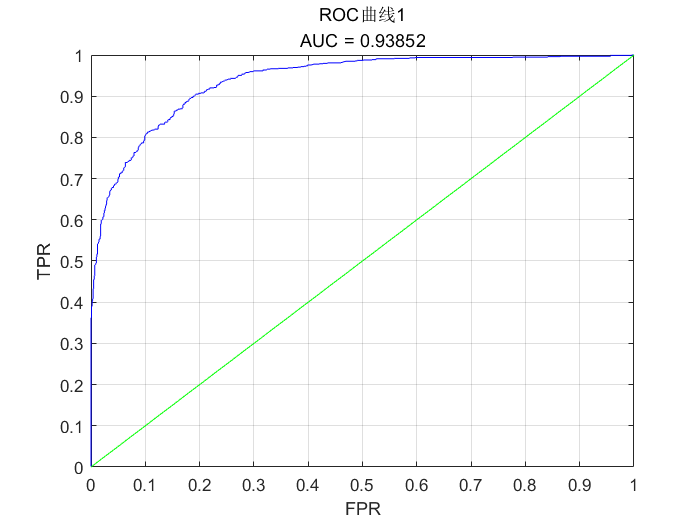

% close 
% [net2,vali_simu2] = naiveBPN(train_x(2:5,:),train_y(2,:),vali_x(2:5,:),[20,20]);

% 
% p=0.5;
% cmx_2=cmatrix(vali_simu2,vali_y(2,:),p);
% [Acc_2,Per_2,rec_2,f1_2]=modelscore(cmx_2)
% [FPR_2,TPR_2,AUC_2] = AUCROC(vali_simu2,vali_y(2,:));
% 
% %画ROC图4
% figure(8)
% plot(FPR_2,TPR_2,'b');
% title({'ROC曲线2', ['AUC = ', num2str(AUC_2)]});
% xlabel("FPR");

Acc_2 = 0.6390

Per_2 = 0.6776

rec_2 = 0.6180

f1_2 = 0.6464

% ylabel("TPR");
% hold on
% grid on
% plot(FPR_2,FPR_2,'g');
% 
% save('netbp_2minus.mat','net2');

#### 6.2.3 第三条分类

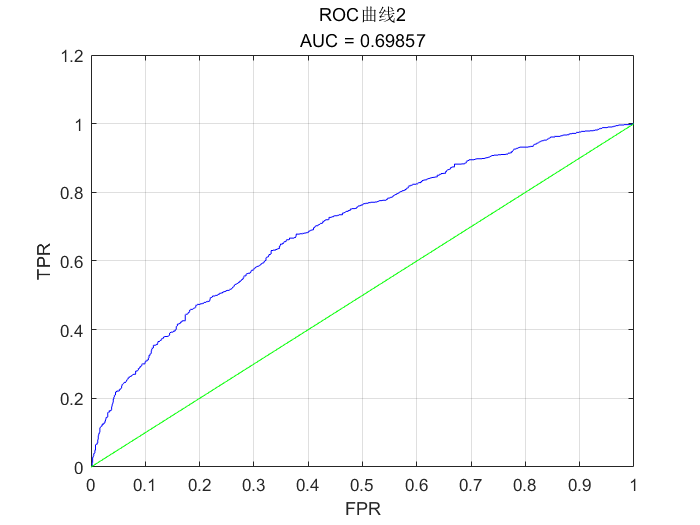

% close
% [net3,vali_simu3] = naiveBPN(train_x(6:9,:),train_y(3,:),vali_x(6:9,:),hiddennum);
% 
% p=0.5;
% cmx_3=cmatrix(vali_simu3,vali_y(3,:),p);

% [Acc_3,Per_3,rec_3,f1_3]=modelscore(cmx_3)
% [FPR_3,TPR_3,AUC_3] = AUCROC(vali_simu3,vali_y(3,:));
% 
% %画ROC图4
% figure(9)
% plot(FPR_3,TPR_3,'b');
% title({'ROC曲线3', ['AUC = ', num2str(AUC_3)]});
% xlabel("FPR");
% ylabel("TPR");
% hold on

Acc_3 = 0.4990

Per_3 = 0.0268

rec_3 = 0.3133

f1_3 = 0.0493

% grid on
% plot(FPR_3,FPR_3,'g');
% 
% save('netbp_3minus.mat','net3');

好有趣捏，不明白捏。但是说明要降维的话，还是要做一个PCA。

### 6.3 主成分分析

按理说主成分分析应该是特征工程里面做，但是我前面忘记了，就现在做吧。

希望会有点用。

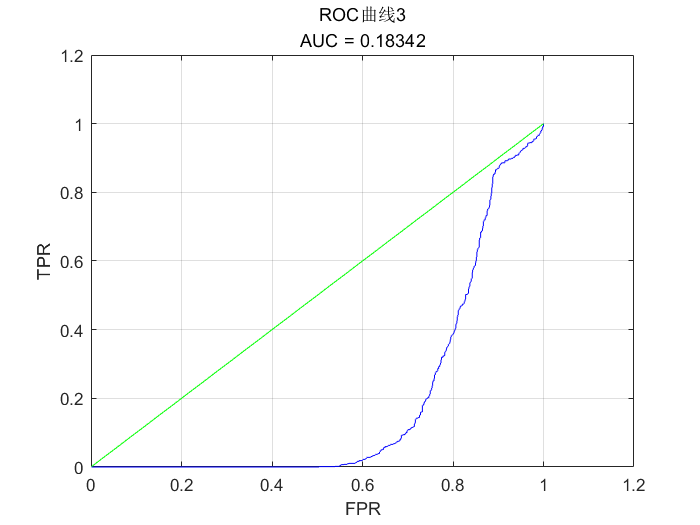

% PCA过程
pcainput=[train_x';vali_x'];
[coeff_pca, score]= pca(pcainput);
train_pcax=score(1:6000,1:6)';
vali_pcax=score(6001:8000,1:6)'

m=mean(vali_x,2)

test_mx=zeros(9,2000);
for i=1:9
    for j=1:2000
    test_mx(i,j)=vali_x(i,j)-m(i);
    end
end

test_pcax=test_mx'*coeff_pca;
test_pcax=test_pcax(:,1:6)'

上面是PCA做数据处理，从九维数据直接变成了六维。这里我单独做了一下原始数据集input（10000*13）的PCA，也是能用的只有六维，从第七维开始数量级就进入-10^13了。

从这个数据重新做一次BP神经网络。

close all
%% BP神经网络
[net_pca,vali_simu_pca] = naiveBPN(train_pcax,train_y,vali_pcax,[30,30]);

%% 混淆矩阵
p=0.5;
cmx_pca1=cmatrix(vali_simu_pca(1,:),vali_y(1,:),p);
cmx_pca2=cmatrix(vali_simu_pca(2,:),vali_y(2,:),p);
cmx_pca3=cmatrix(vali_simu_pca(3,:),vali_y(3,:),p);

%% 分类结果
cmx_pca_all=Classify_all(vali_simu_pca,vali_y,p)

%% 模型评价
[Acc_pca1,Per_pca1,rec_pca1,f1_pca1]=modelscore(cmx_pca1)

cmx_pca_all =         1610
         390


[Acc_pca2,Per_pca2,rec_pca2,f1_pca2]=modelscore(cmx_pca2)
[Acc_pca3,Per_pca3,rec_pca3,f1_pca3]=modelscore(cmx_pca3)


Acc_pca1 = 0.9245

Per_pca1 = 0.9337

rec_pca1 = 0.9183

f1_pca1 = 0.9259

Acc_pca_all=cmx_pca_all(1)/length(vali_y(1,:))

Acc_pca2 = 0.9230

Per_pca2 = 0.9415

rec_pca2 = 0.9043

f1_pca2 = 0.9225

Acc_pca3 = 0.9475

Per_pca3 = 0.9609

rec_pca3 = 0.9330

f1_pca3 = 0.9467

[FPR_pca_p1,TPR_pca_p1,AUC_pca1] = AUCROC(vali_simu_pca(1,:),vali_y(1,:));
[FPR_pca_p2,TPR_pca_p2,AUC_pca2] = AUCROC(vali_simu_pca(2,:),vali_y(2,:));

Acc_pca_all = 0.8050

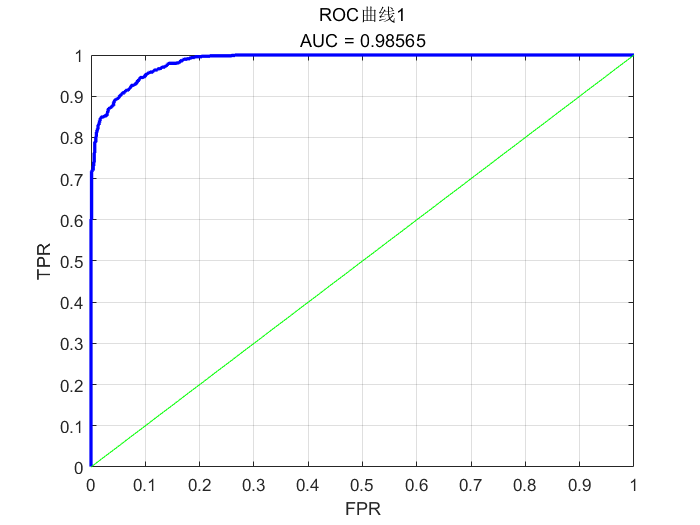

[FPR_pca_p3,TPR_pca_p3,AUC_pca3] = AUCROC(vali_simu_pca(3,:),vali_y(3,:));

%画ROC图1
figure(10)
plot(FPR_pca_p1,TPR_pca_p1,'b',"LineWidth",2);
title({'ROC曲线1', ['AUC = ', num2str(AUC_pca1)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_pca_p1,FPR_pca_p1,'g');

%画ROC图2
figure(11)

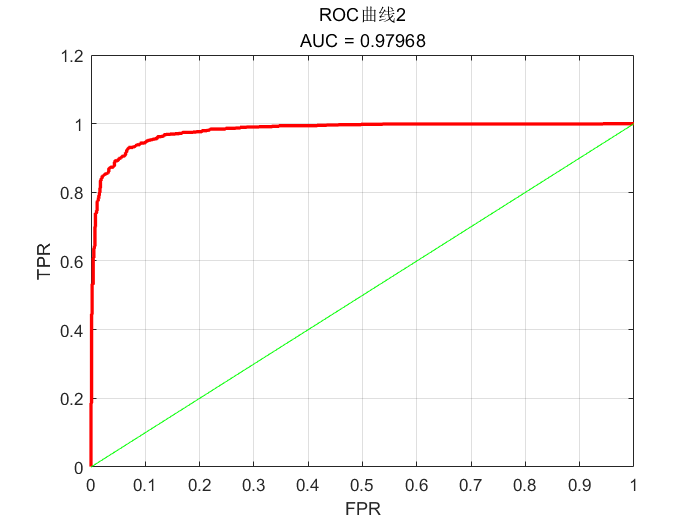

plot(FPR_pca_p2,TPR_pca_p2,'r',"LineWidth",2);
title({'ROC曲线2', ['AUC = ', num2str(AUC_pca2)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_pca_p2,FPR_pca_p2,'g');

%画ROC图3
figure(12)

plot(FPR_pca_p3,TPR_pca_p3,'k',"LineWidth",2);
title({'ROC曲线3', ['AUC = ', num2str(AUC_pca3)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_pca_p3,FPR_pca_p3,'g');

save('netbp_pca.mat','net_pca');

### 6.4 做一个简单的验证

这里我们得到了两个有效的模型，直接做的netbp1.mat，和用了主主成分分析的netbp_pca.mat。

把验证集和主成分分析处理一下的验证集代入看看。

#### 6.4.1 直接模型评价

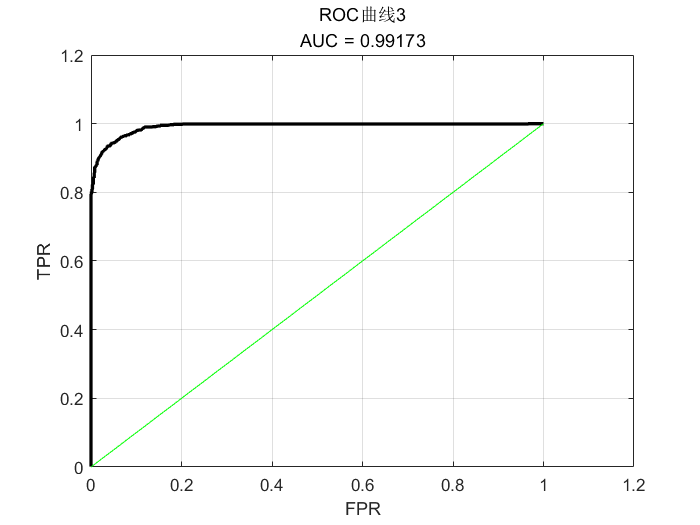

test = sim(net, vali_x);

%% 混淆矩阵
p=0.5;
cmx_v1=cmatrix(test(1,:),vali_y(1,:),p);
cmx_v2=cmatrix(test(2,:),vali_y(2,:),p);
cmx_v3=cmatrix(test(3,:),vali_y(3,:),p);

%% 分类结果
cmx_vall=Classify_all(test,vali_y,p)

%% 模型评价
[Acc_v1,Per_v1,rec_v1,f1_v1]=modelscore(cmx_v1)
[Acc_v2,Per_v2,rec_v2,f1_v2]=modelscore(cmx_v2)
[Acc_v3,Per_v3,rec_v3,f1_v3]=modelscore(cmx_v3)

Acc_vall=cmx_vall(1)/length(test_y(1,:))


cmx_vall =         1647
         353


[FPR_v1,TPR_v1,AUC_v1] = AUCROC(test(1,:),vali_y(1,:));
[FPR_v2,TPR_v2,AUC_v2] = AUCROC(test(2,:),vali_y(2,:));
[FPR_v3,TPR_v3,AUC_v3] = AUCROC(test(3,:),vali_y(3,:));

Acc_v1 = 0.9345

Per_v1 = 0.9436

rec_v1 = 0.9280

f1_v1 = 0.9358

Acc_v2 = 0.9295

Per_v2 = 0.9343

rec_v2 = 0.9220

f1_v2 = 0.9281

%画ROC图1

Acc_v3 = 0.9495

Per_v3 = 0.9464

rec_v3 = 0.9494

f1_v3 = 0.9479

figure(13)
plot(FPR_v1,TPR_v1,'b');

Acc_vall = 0.8235

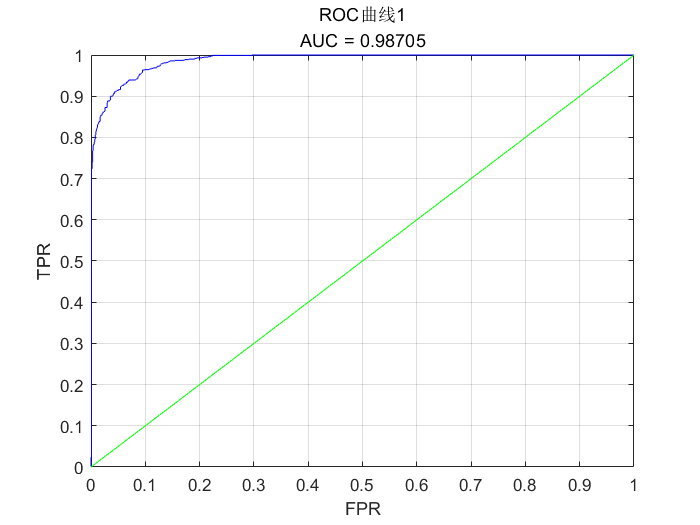

title({'ROC曲线1', ['AUC = ', num2str(AUC_v1)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_v1,FPR_v1,'g');

%画ROC图2
figure(14)
plot(FPR_v2,TPR_v2,'r');
title({'ROC曲线2', ['AUC = ', num2str(AUC_v2)]});
xlabel("FPR");
ylabel("TPR");
hold on

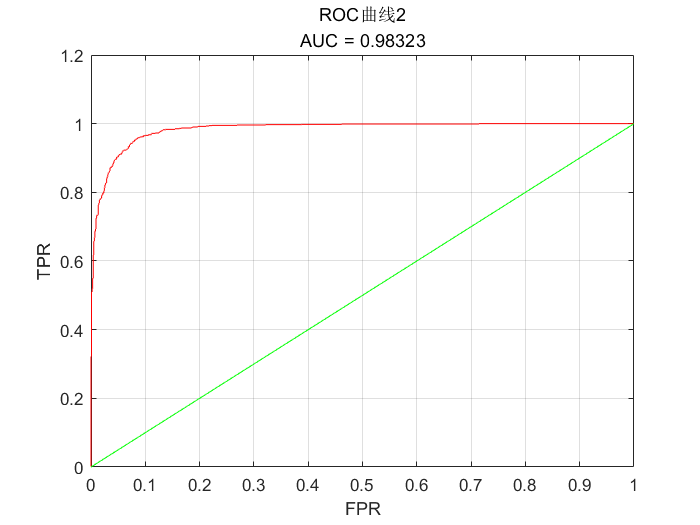

grid on
plot(FPR_v2,FPR_v2,'g');

%画ROC图3
figure(15)
plot(FPR_v3,TPR_v3,'k');
title({'ROC曲线3', ['AUC = ', num2str(AUC_v3)]});
xlabel("FPR");
ylabel("TPR");
hold on

grid on
plot(FPR_v3,FPR_v3,'g');

#### 6.4.2 主成分分析模型评价

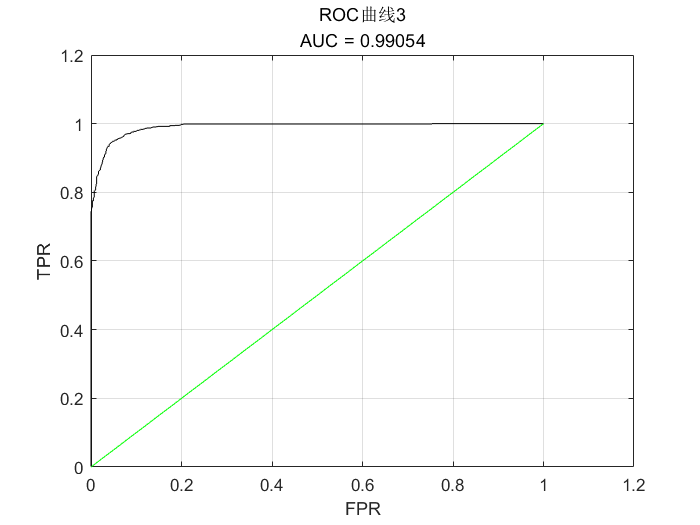

test_pca = sim(net_pca, vali_pcax);
%% 混淆矩阵
p=0.5;
cmx_pcav1=cmatrix(test_pca(1,:),vali_y(1,:),p);
cmx_pcav2=cmatrix(test_pca(2,:),vali_y(2,:),p);
cmx_pcav3=cmatrix(test_pca(3,:),vali_y(3,:),p);

%% 分类结果

cmx_pcavall=Classify_all(test_pca,vali_y,p)

%% 模型评价
[Acc_pcav1,Per_pcav1,rec_pcav1,f1_pcav1]=modelscore(cmx_pcav1)
[Acc_pcav2,Per_pcav2,rec_pcav2,f1_pcav2]=modelscore(cmx_pcav2)
[Acc_pcav3,Per_pcav3,rec_pcav3,f1_pcav3]=modelscore(cmx_pcav3)

Acc_pcavall=cmx_pcavall(1)/length(vali_y(1,:))

[FPR_pcav1,TPR_pcav1,AUC_pcav1] = AUCROC(test_pca(1,:),vali_y(1,:));
[FPR_pcav2,TPR_pcav2,AUC_pcav2] = AUCROC(test_pca(2,:),vali_y(2,:));

cmx_pcavall =          265
        1735


[FPR_pcav3,TPR_pcav3,AUC_pcav3] = AUCROC(test_pca(3,:),vali_y(3,:));

%画ROC图1

Acc_pcav1 = 0.5090

Per_pcav1 = 0.3383

rec_pcav1 = 0.5221

f1_pcav1 = 0.4106

figure(16)

Acc_pcav2 = 0.5205

Per_pcav2 = 0.6129

rec_pcav2 = 0.5064

f1_pcav2 = 0.5546

plot(FPR_pcav1,TPR_pcav1,'b');

Acc_pcav3 = 0.5010

Per_pcav3 = 0.0113

rec_pcav3 = 0.2245

f1_pcav3 = 0.0216

title({'ROC曲线1', ['AUC = ', num2str(AUC_pcav1)]});
xlabel("FPR");

Acc_pcavall = 0.1325

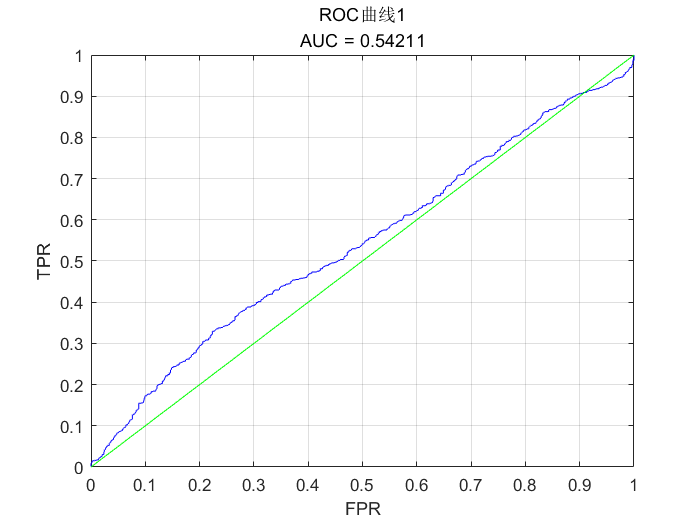

ylabel("TPR");
hold on
grid on
plot(FPR_pcav1,FPR_pcav1,'g');

%画ROC图2
figure(17)
plot(FPR_pcav2,TPR_pcav2,'r');
title({'ROC曲线2', ['AUC = ', num2str(AUC_pcav2)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_pcav2,FPR_pcav2,'g');

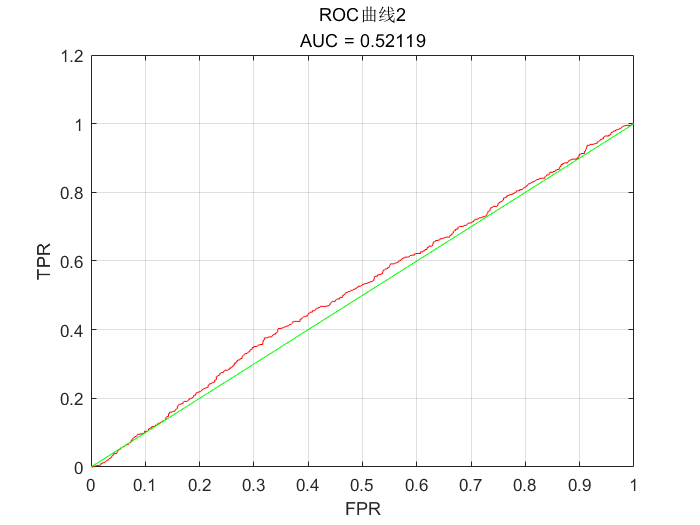


%画ROC图3
figure(18)
plot(FPR_pcav3,TPR_pcav3,'k');
title({'ROC曲线3', ['AUC = ', num2str(AUC_pcav3)]});
xlabel("FPR");
ylabel("TPR");
hold on
grid on
plot(FPR_pcav3,FPR_pcav3,'g');

好家伙，越做越烂，不想做了。

直接上优化吧。

### 6.5 交叉验证网格搜索

这一步工作旨在优化模型参数，以获得更高的Accuracy和F1-score。优化策略为网格搜索交叉验证，可搜索的参数为：

- 激活函数：